% Завантаження початкових зображень
imgHero   = imread('imgFolder/hero.jpg');      
imgMask   = imread('imgFolder/mask.jpg');      
imgCam    = imread('cameraman.tif');       

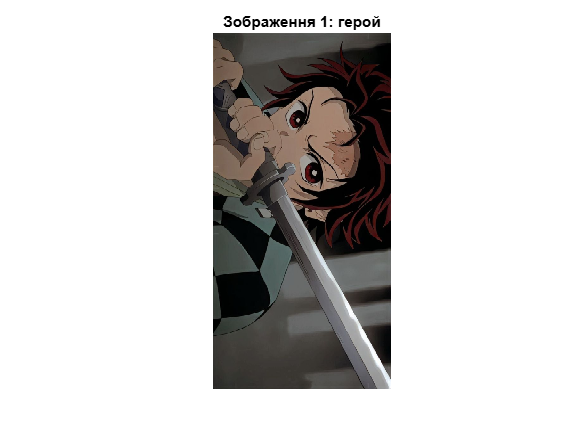

% Відображення кольорових зображень
figure; imshow(imgHero); title('Зображення 1: герой');

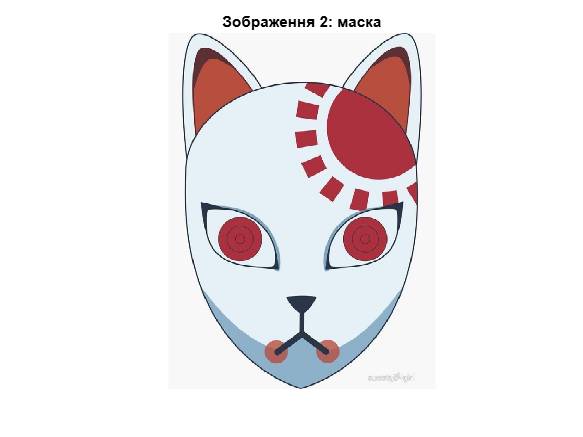

figure; imshow(imgMask); title('Зображення 2: маска');

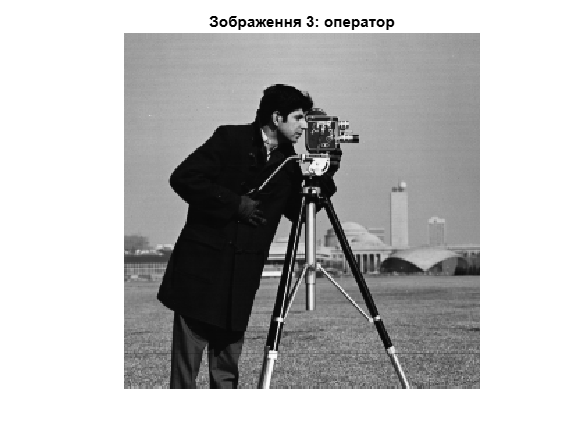

figure; imshow(imgCam);  title('Зображення 3: оператор');

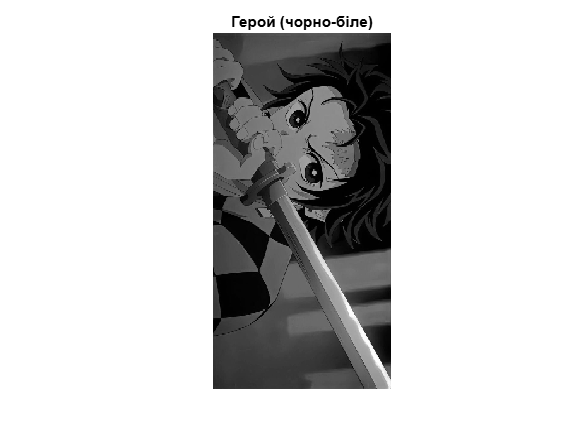

% Перетворення в градації сірого (для RGB-зображень)
grayHero  = rgb2gray(imgHero);             % герой → сіре
grayMask  = rgb2gray(imgMask);             % маска → сіре
grayCam   = imgCam;                        % вже чорно-біле

figure; imshow(grayHero); title('Герой (чорно-біле)');

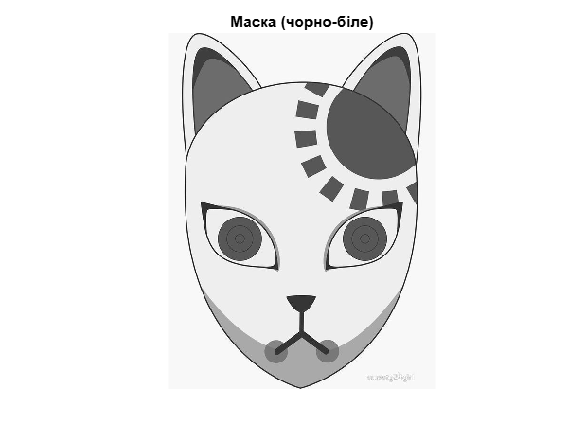

figure; imshow(grayMask); title('Маска (чорно-біле)');

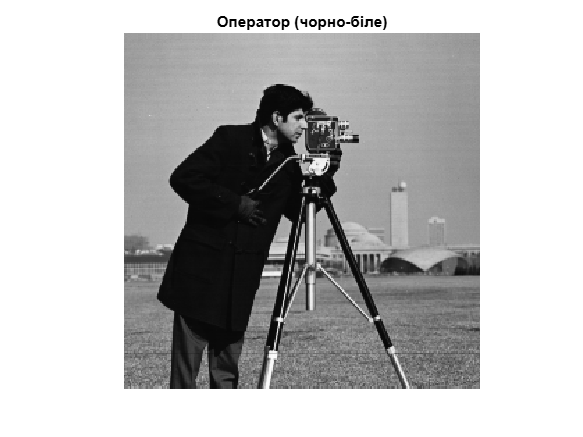

figure; imshow(grayCam);  title('Оператор (чорно-біле)');

% Виконання DCT (дискретного косинусного перетворення)
dctHero   = dct2(grayHero);
dctMask   = dct2(grayMask);
dctCam    = dct2(grayCam);

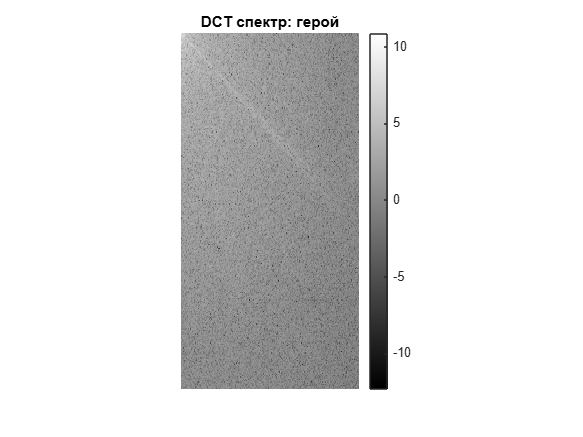

% Візуалізація спектрів DCT в логарифмічній шкалі
figure; imshow(log(abs(dctHero)), []), colorbar
title('DCT спектр: герой');

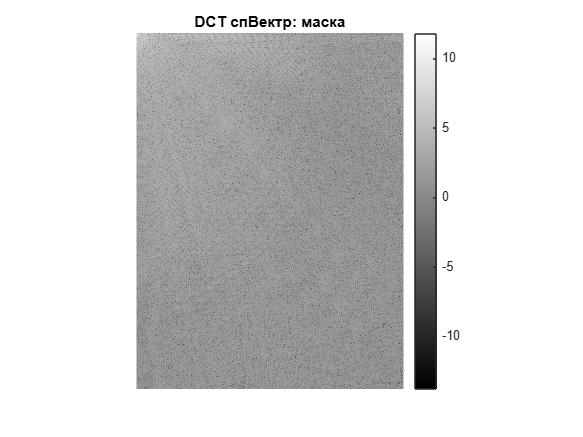


figure; imshow(log(abs(dctMask)), []), colorbar
title('DCT спВектр: маска');

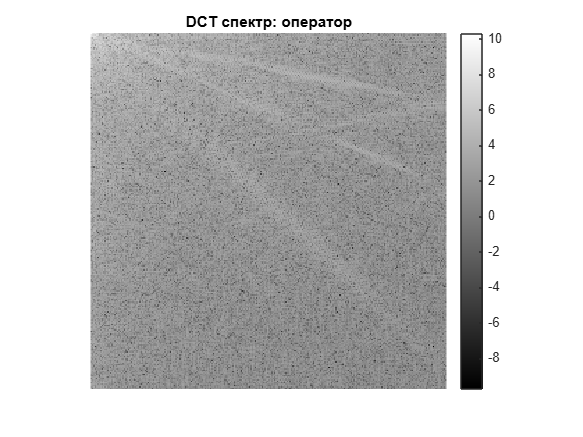


figure; imshow(log(abs(dctCam)),  []), colorbar
title('DCT спектр: оператор');

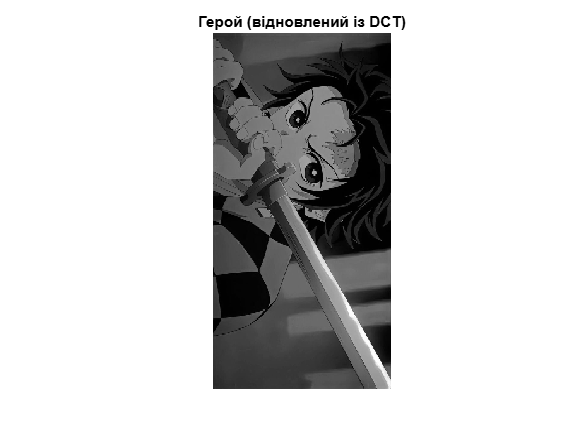

% Відновлення зображень через обернене DCT
reconHero = idct2(dctHero);
reconMask = idct2(dctMask);
reconCam  = idct2(dctCam);

figure; imshow(reconHero, [0 255]); title('Герой (відновлений із DCT)');

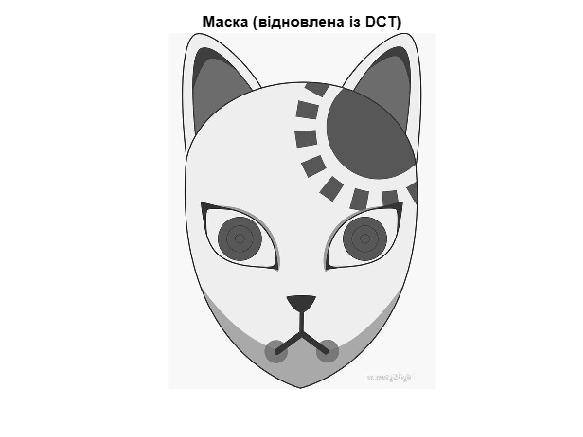

figure; imshow(reconMask, [0 255]); title('Маска (відновлена із DCT)');

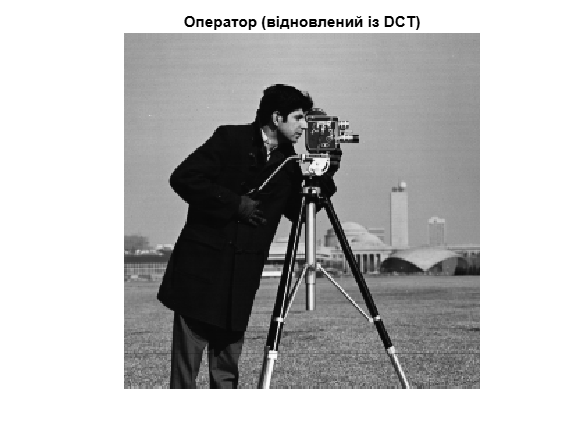

figure; imshow(reconCam,  [0 255]); title('Оператор (відновлений із DCT)');

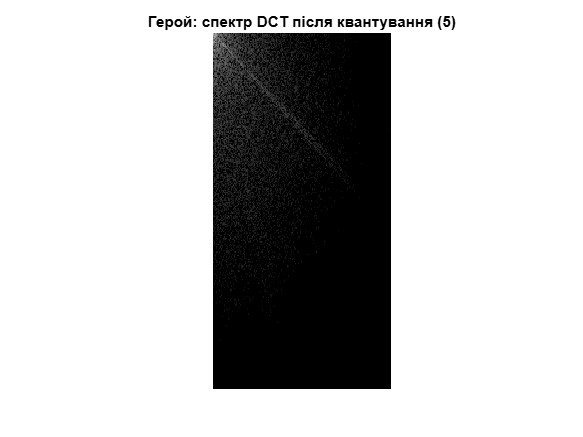

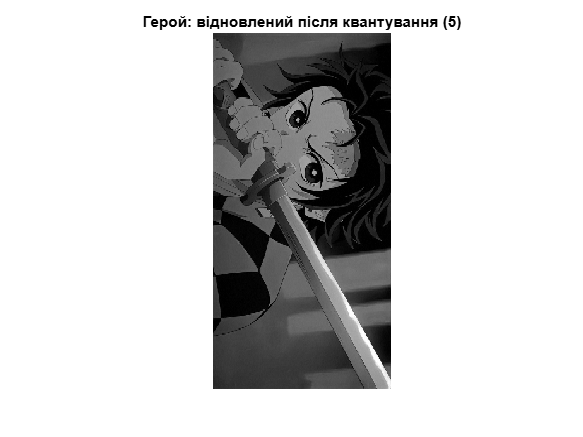

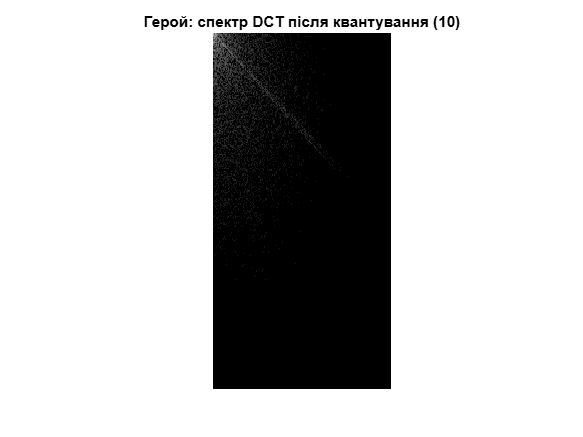

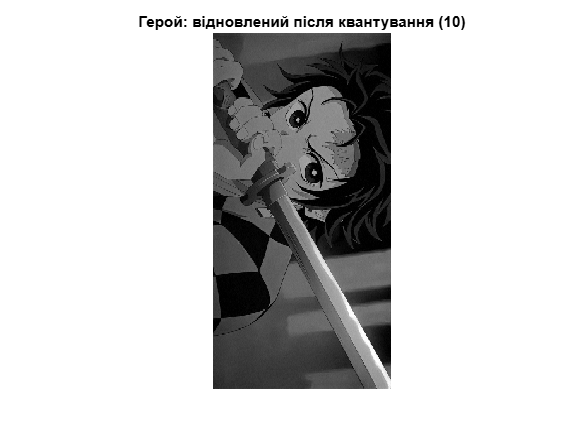

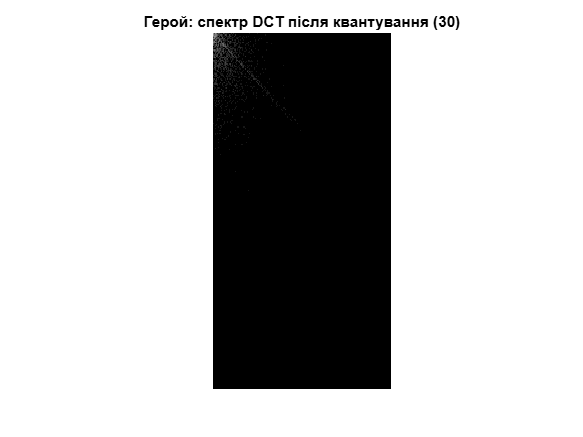

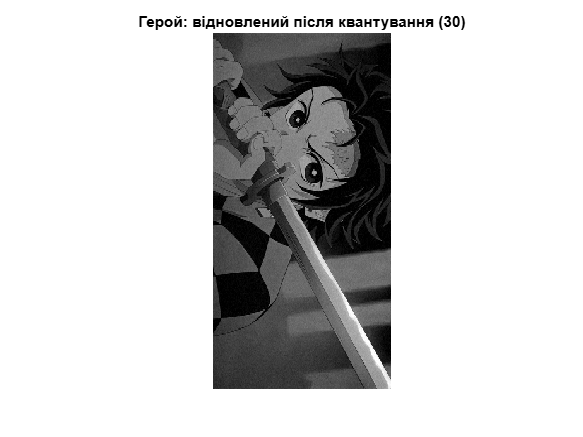

% Квантування DCT-коефіцієнтів для різних кроків
steps = [5, 10, 30];
% ——— 1) Герой — DCT-квантування та відновлення ———
for idx = 1:numel(steps)
    q = steps(idx);
    
    % квантуємо DCT-коефіцієнти героя
    dctHeroQ = q * round(dctHero / q);
    
    % показуємо спектр після квантування
    figure; 
    imshow(log(abs(dctHeroQ)), []); 
    title(sprintf('Герой: спектр DCT після квантування (%d)', q));
    
    % відновлюємо зображення з квантуваних коефіцієнтів
    reconHeroQ = idct2(dctHeroQ);
    figure; 
    imshow(reconHeroQ, [0 255]); 
    title(sprintf('Герой: відновлений після квантування (%d)', q));
end

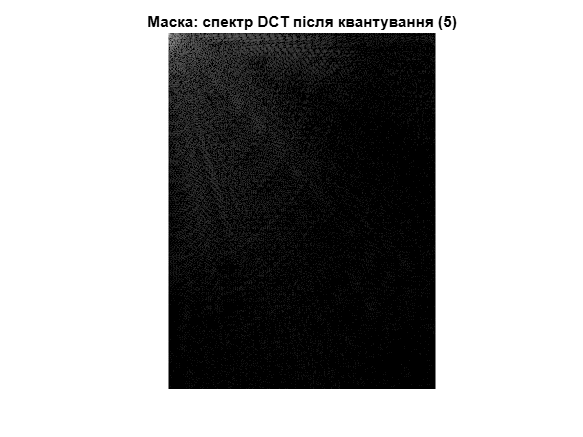

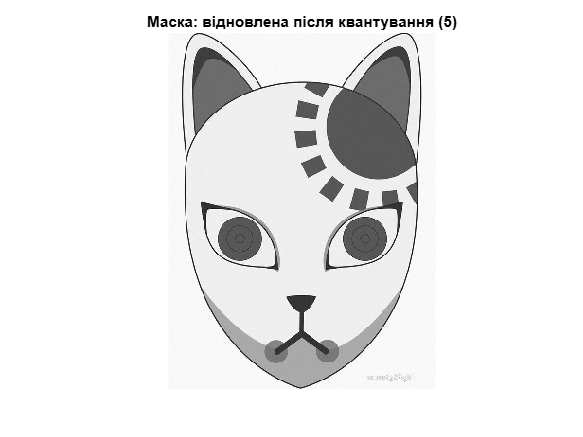

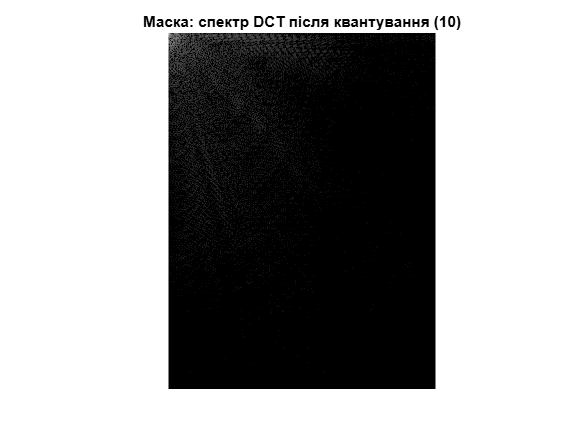

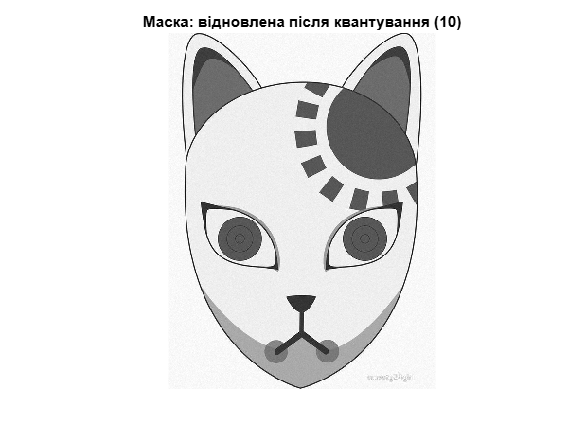

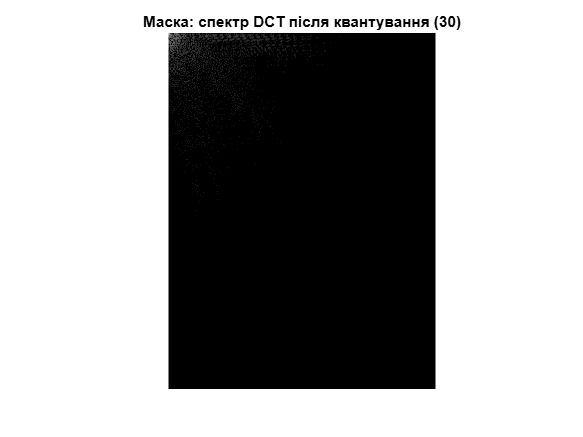

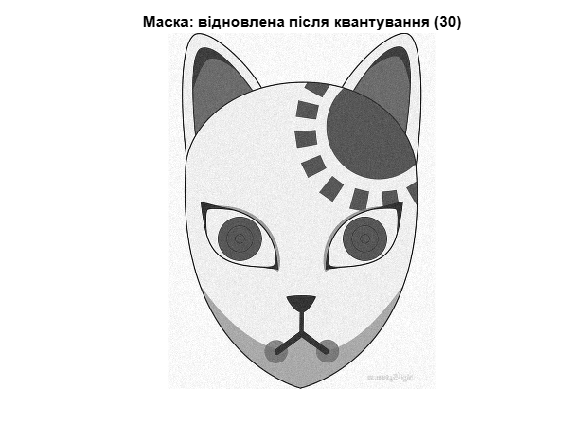

% ——— 2) Маска — DCT-квантування та відновлення ———
for idx = 1:numel(steps)
    q = steps(idx);
    
    % квантуємо DCT-коефіцієнти маски
    dctMaskQ = q * round(dctMask / q);
    
    % показ спектру
    figure; 
    imshow(log(abs(dctMaskQ)), []); 
    title(sprintf('Маска: спектр DCT після квантування (%d)', q));
    
    % відновлення із квантування
    reconMaskQ = idct2(dctMaskQ);
    figure; 
    imshow(reconMaskQ, [0 255]); 
    title(sprintf('Маска: відновлена після квантування (%d)', q));
end

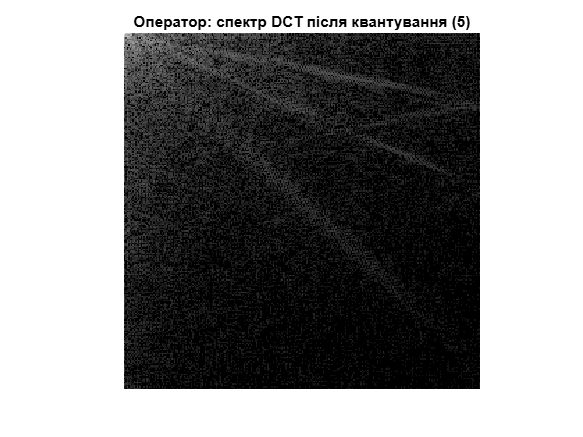

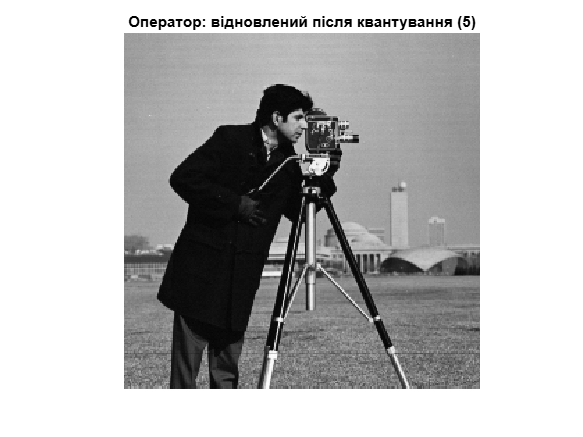

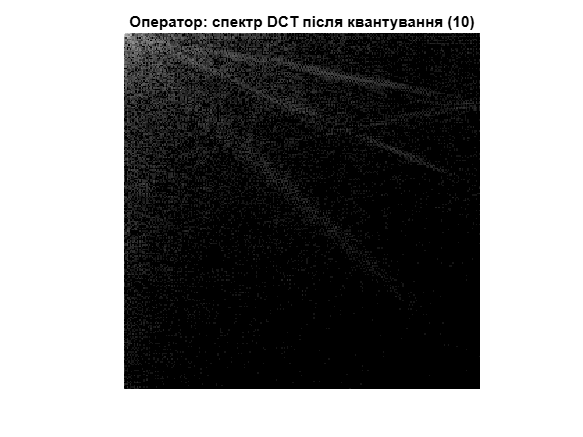

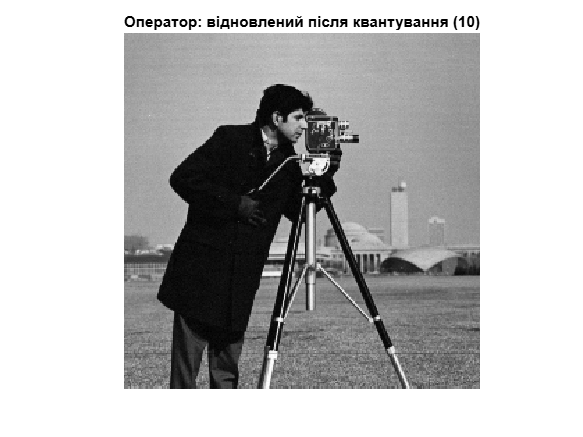

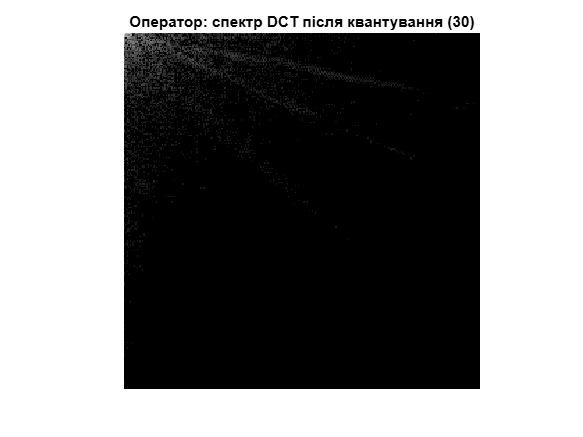

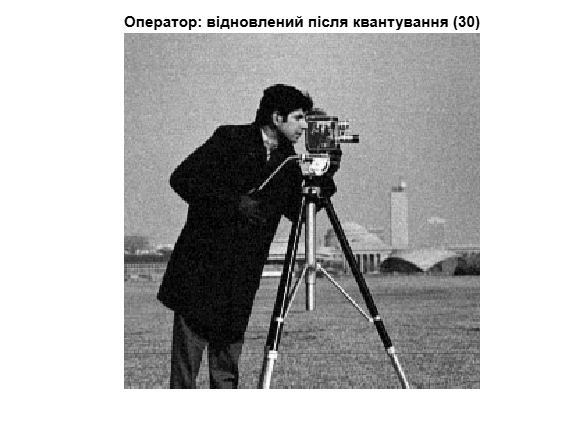

% ——— 3) Оператор — DCT-квантування та відновлення ———
for idx = 1:numel(steps)
    q = steps(idx);
    
    % квантуємо DCT-коефіцієнти оператора
    dctCamQ = q * round(dctCam / q);
    
    % візуалізація спектру
    figure; 
    imshow(log(abs(dctCamQ)), []); 
    title(sprintf('Оператор: спектр DCT після квантування (%d)', q));
    
    % відновлене зображення
    reconCamQ = idct2(dctCamQ);
    figure; 
    imshow(reconCamQ, [0 255]); 
    title(sprintf('Оператор: відновлений після квантування (%d)', q));
end

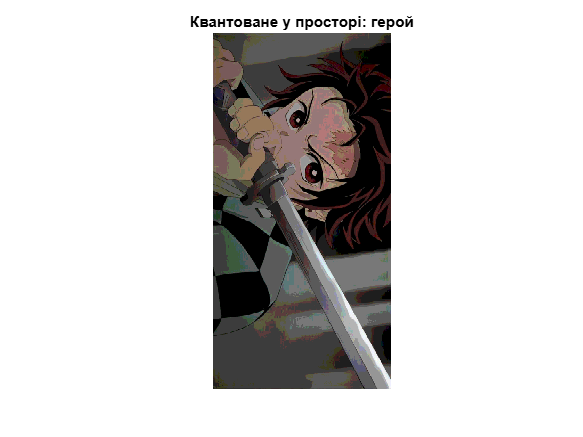

% Просте квантування в просторі зображення
spaceStep = 30;  % крок квантування пікселів
imgHeroQ  = uint8(round(double(imgHero) / spaceStep) * spaceStep);
imgMaskQ  = uint8(round(double(imgMask) / spaceStep) * spaceStep);
imgCamQ   = uint8(round(double(imgCam)  / spaceStep) * spaceStep);

figure; imshow(imgHeroQ); title('Квантоване у просторі: герой');

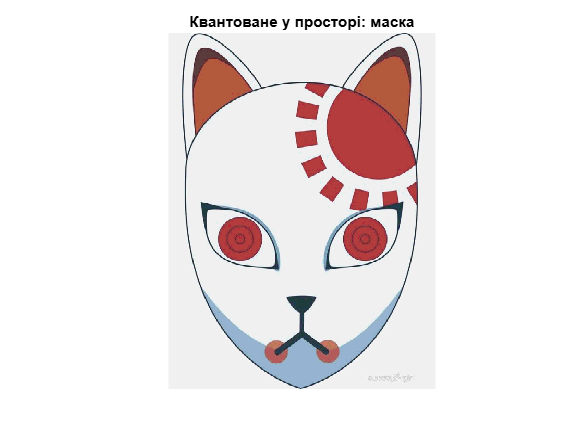

figure; imshow(imgMaskQ); title('Квантоване у просторі: маска');

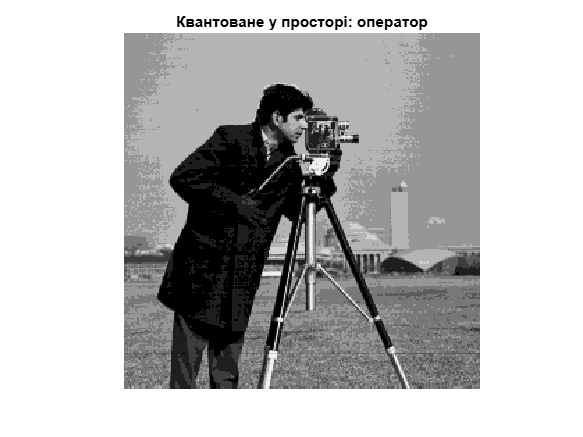

figure; imshow(imgCamQ);  title('Квантоване у просторі: оператор');